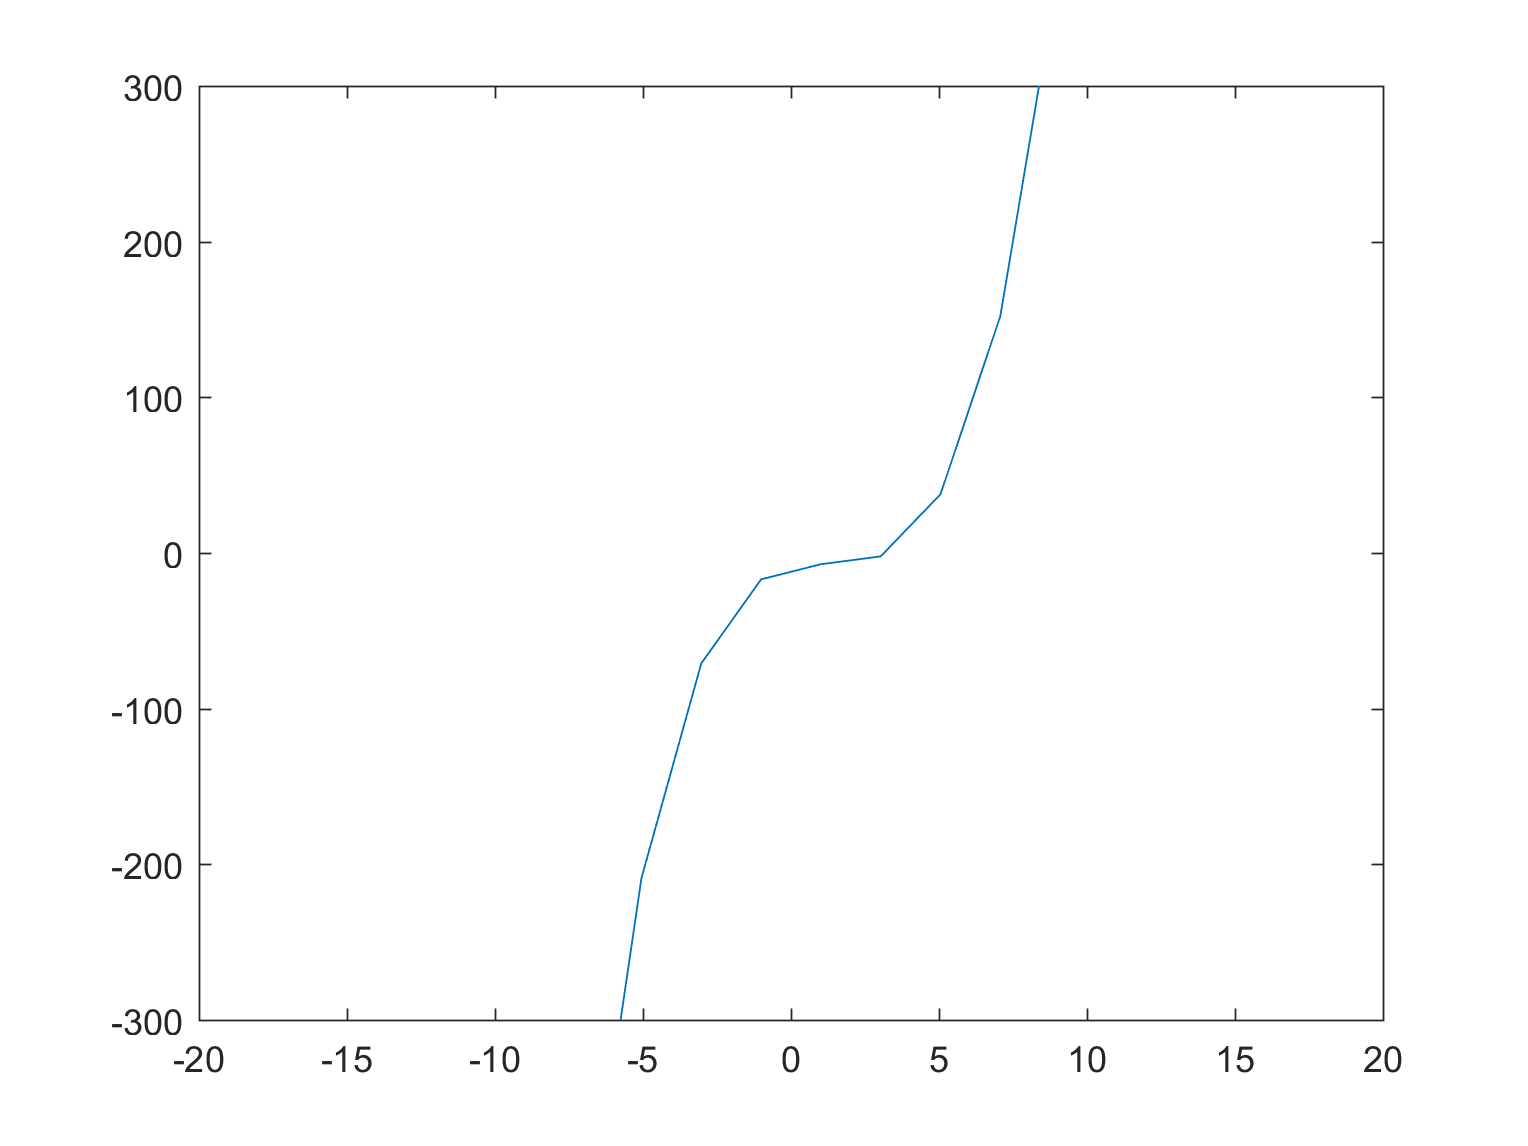

%Practice
clear; clc;

x=linspace(-100,100,100);
coeffs = [0.8 -3,4,-9];
y = polyval(coeffs, x);
plot(x,y)
axis([-20 20 -300 300])

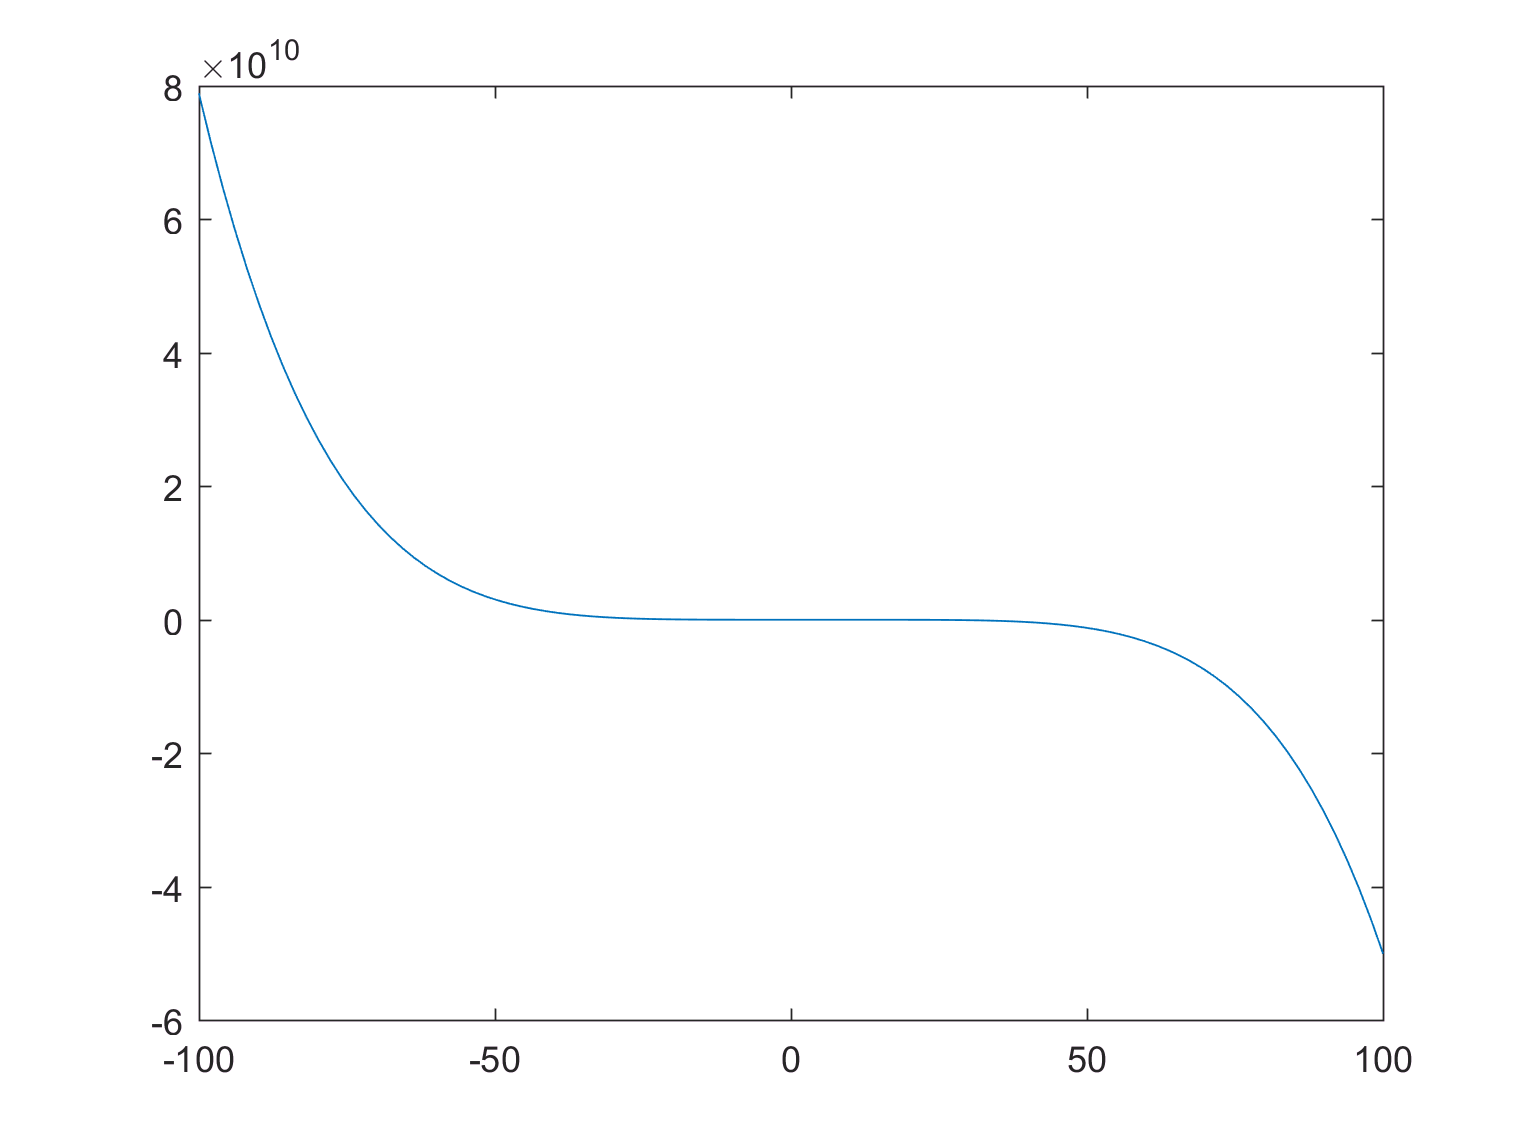


x=linspace(-100,100,100);
xpts = [1 4 2 6 5 8];
ypts = [654 234 6 2 3 7];
coeff = polyfit(xpts, ypts, 5);
y = polyval(coeff, x);
plot(x,y);

%Engineering Mission #1: Chillin’ with the Penicillin
clear; clc;




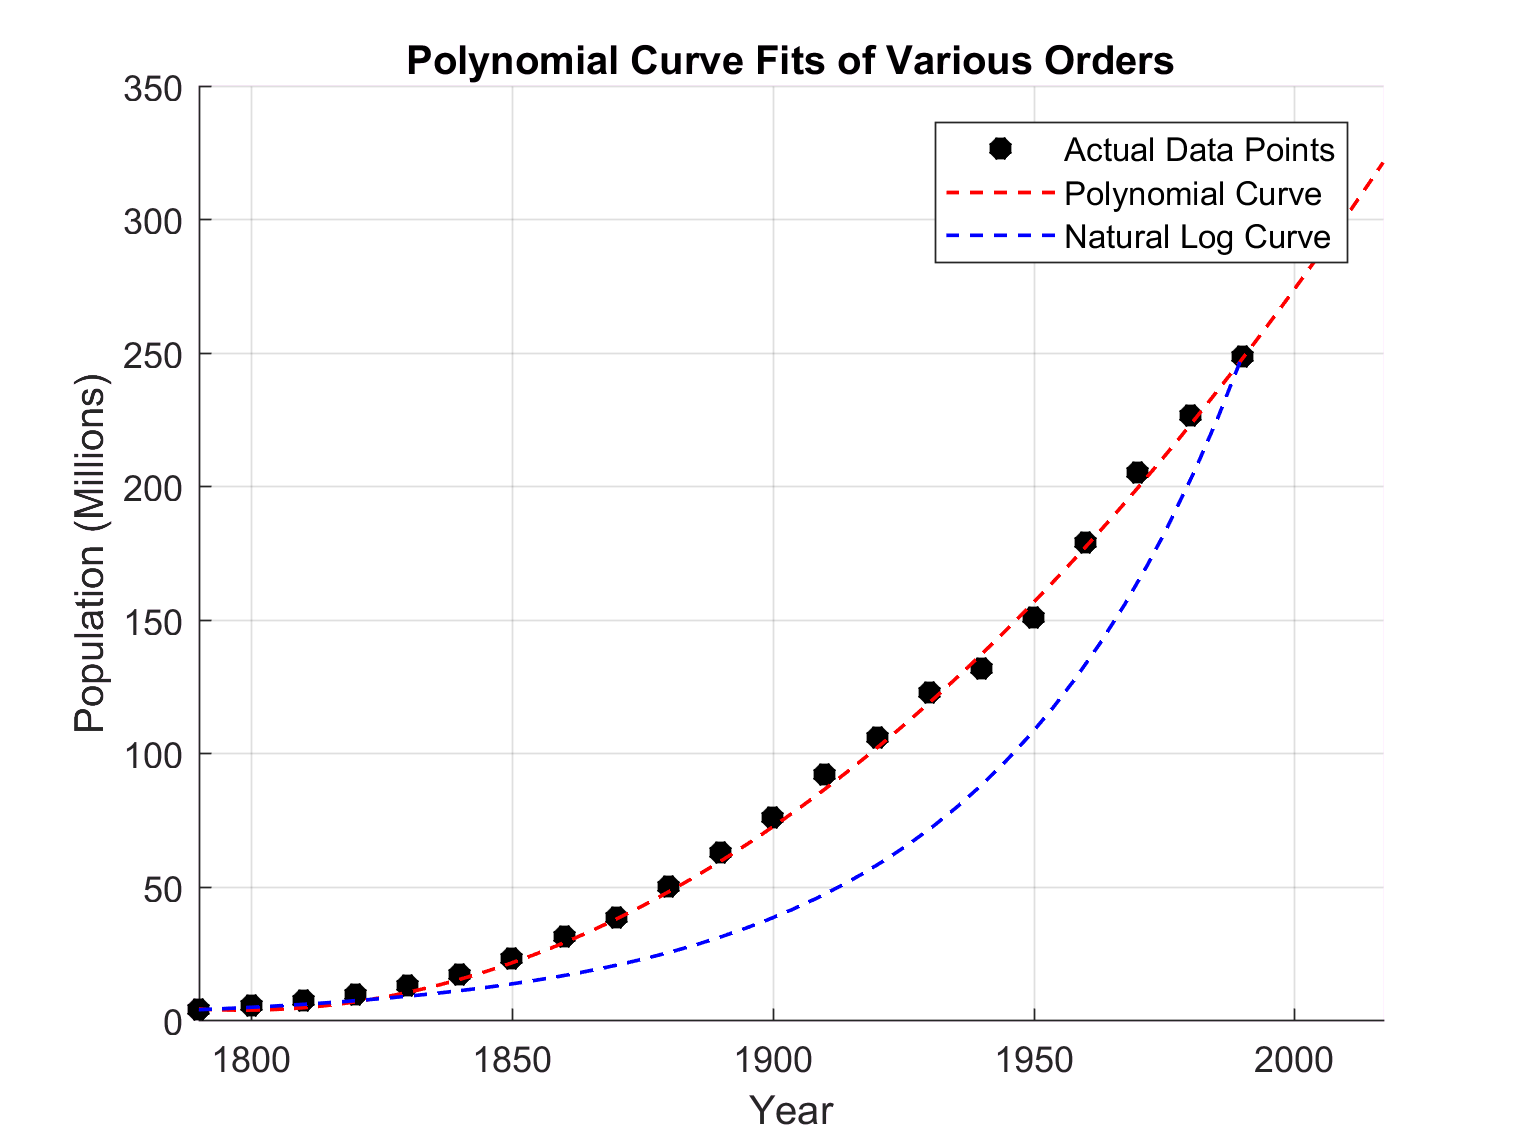

%Engineering Mission #2: Population Investigation
clc; clear all; close all;

% load and plot census data
load census;
hold on;
plot(cdate, pop, '*black', 'LineWidth', 3);
grid on;

% set up variables
x = linspace(1790, 2017, 2017-1790);
xpts = [1790 1870 1930 1940 1990];
ypts = [3.9 38.6 122.8 131.7 248.7];

% bulld function and plot
coeffs = polyfit(xpts, ypts, 2);
y = polyval(coeffs, x);
plot(x, y, '--r', 'LineWidth', 1);



%Create natural log function
A = 3.9;
x1 = 1990;
y1 = 248.7;

% solve for k
syms k t;
b = solve(y1 == A*exp(k*(x1-1790)));

% create function
yt(t) = A*exp(b*(t-1790));

% plot function
fplot(yt(t), [1790 1990], '--b', 'LineWidth', 1);
xlim([1790 2017]);
title('Polynomial Curve Fits of Various Orders');
xlabel('Year');
ylabel('Population (Millions)');
legend('Actual Data Points', 'Polynomial Curve', 'Natural Log Curve')
hold off;

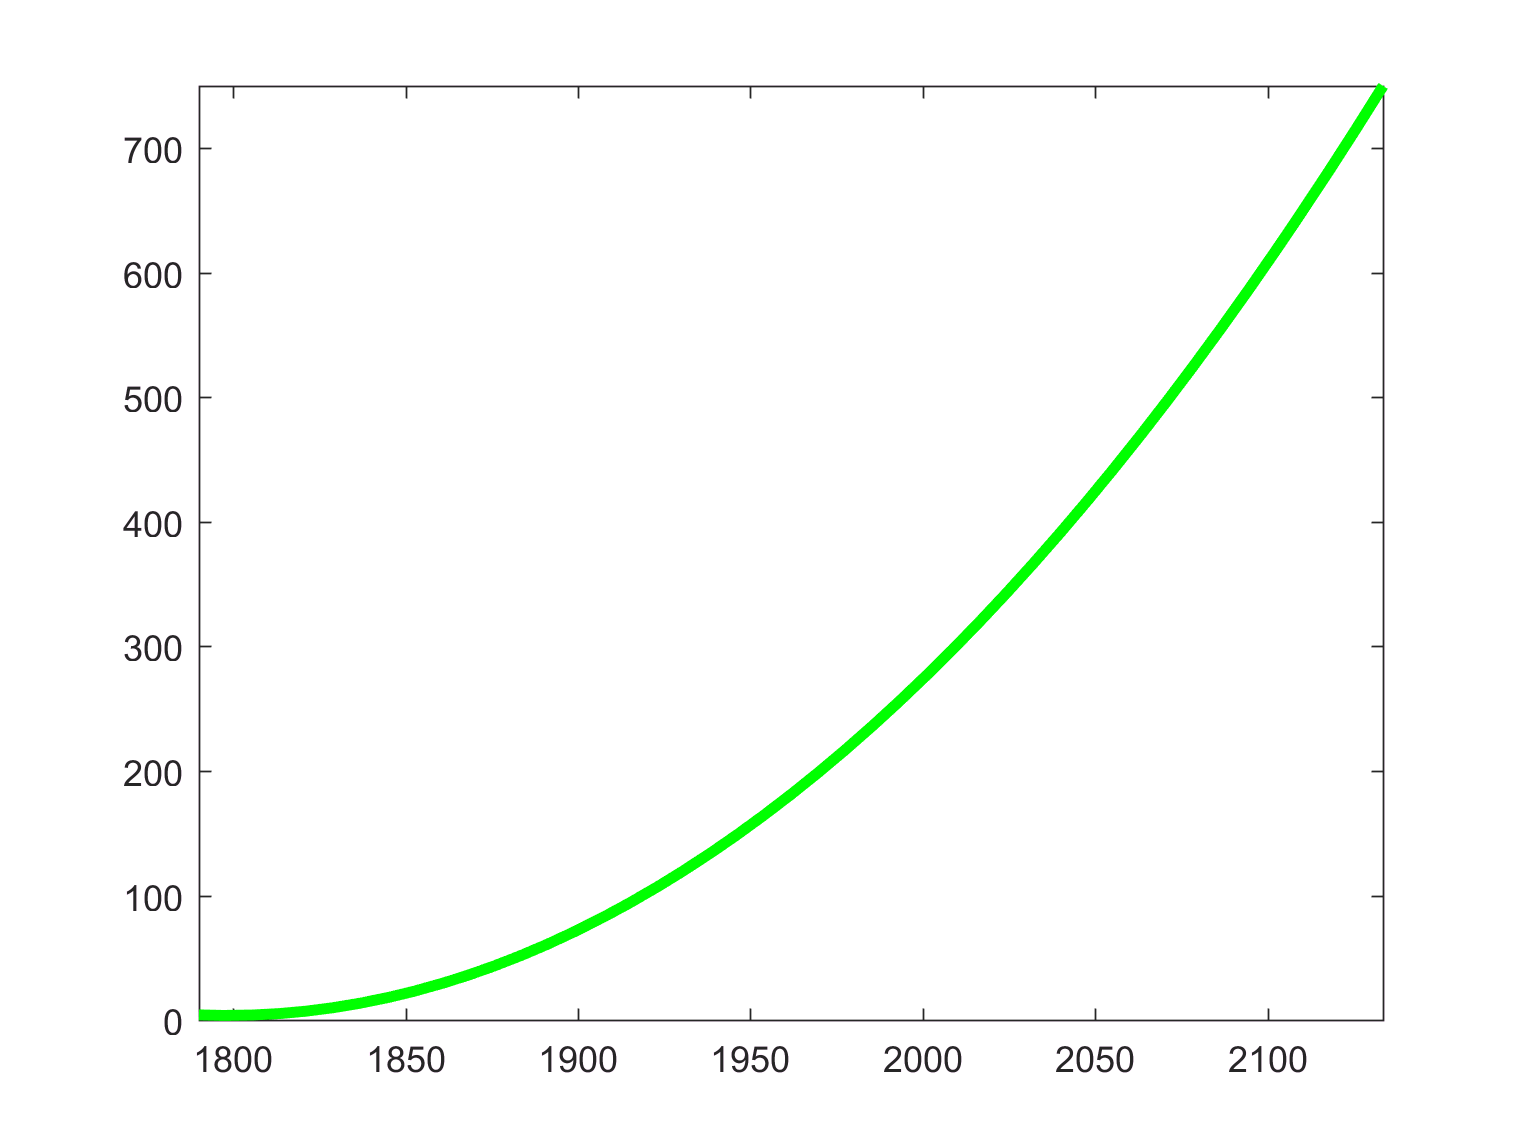


f(t) = 0.00664094035777587*t^2 + -23.8850235856428*t + 21480.1426835660;
fplot(f(t), [1790 2133.5], '-g', 'LineWidth', 3);

max = solve(f(t) == 750)

$$max = \left(\begin{array}{c} \frac{13768778664964661248}{7656482949291289}-\frac{2048\,\sqrt{1570602218696616907319438824143}}{7656482949291289}\\ \frac{2048\,\sqrt{1570602218696616907319438824143}}{7656482949291289}+\frac{13768778664964661248}{7656482949291289} \end{array}\right)$$

max1 = eval(max)

max1 =    1.0e+03 *

    1.4631
    2.1335



%Answers:
%d. The polynomial function of degree 2 seems to be more realistic as the better model of the real-life situation.
%e. The plot at x = 2017 does match the ~326 million US population on the website.
%f. Year 2133.5 because of exponential growth of population

% Limitations:
% approximation of using only 5 data points.
% function does not consider carrying capacity
% function is valid only for a certain interval of time (ex: does not work for years prior to 1790)